g = 9.8;
I_xx = 1.295e-5;

I_xx = Principal moment of Inertia around x axis

g = gravity acceleration

p = Roll angular velocity 

v = Y linear velocity of CoG

ф = roll angle

y = Y position of CoG in the interatial form

M_x = I_xx * grad(p')

% Задаем модель
A = [0  0  0  0 ;
     1  0  0  0 ;
     0 -g  0  0 ;
     0  0  1  0 ];

B = [1/I_xx;
     0;
     0;
     0];

C = [0 0 0 1;
     0 0 1 0;
     0 1 0 0;
     1 0 0 0];

D = [0;
    0;
    0;
    0];
%---------------------------------
Q = eye(4);
R = 1;
%K = lqr(A, B, Q, R)
P = icare(A, B, Q, R);
K = R^-1*B'*P;

Теперь составим эталонную систему систему

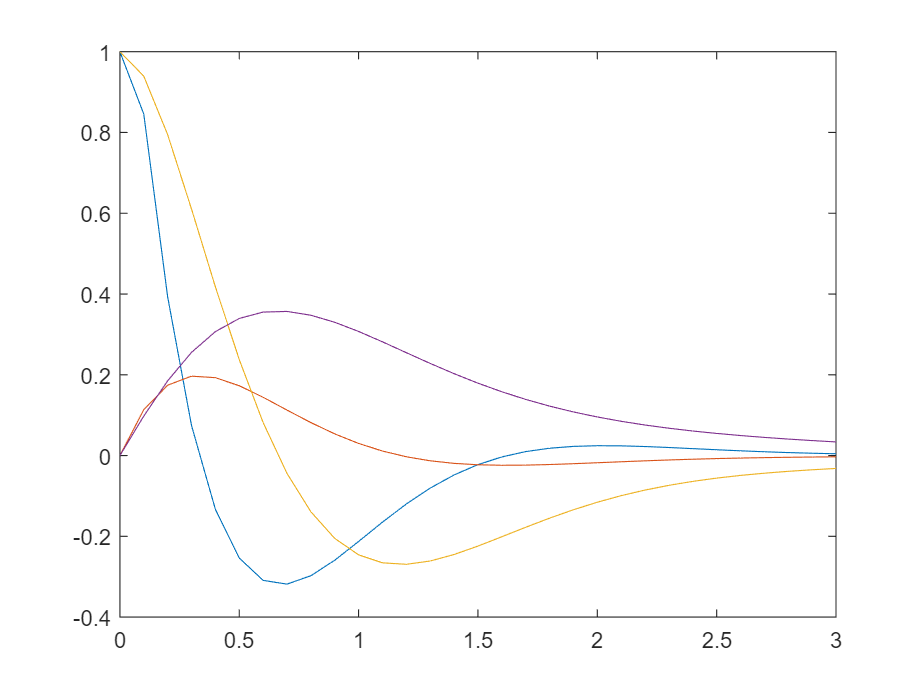

A_m= A - B*K;
B_m = B;
T = 3;

tspan = 0:0.1:T;

initConds = [1 0 1 0];
x_m = initConds;
Theta = [1];
ICs = [x_ic, x_m, Theta];

% референсная задающая функция
g = @(t) 0;
%g = @(t) [cos(t)];
g_vals = cell2mat(arrayfun(g, tspan, 'UniformOutput', false));



% исследуем переходные процессы системы
sys_m = ss(A_m, B_m, eye(size(A, 1), size(A,1)) , zeros(size(B, 1), size(B, 2)));

x_m = lsim(sys_m, g_vals, tspan, x_m);
figure('Name', 'Reference model trajectories');
plot(tspan, x_m);

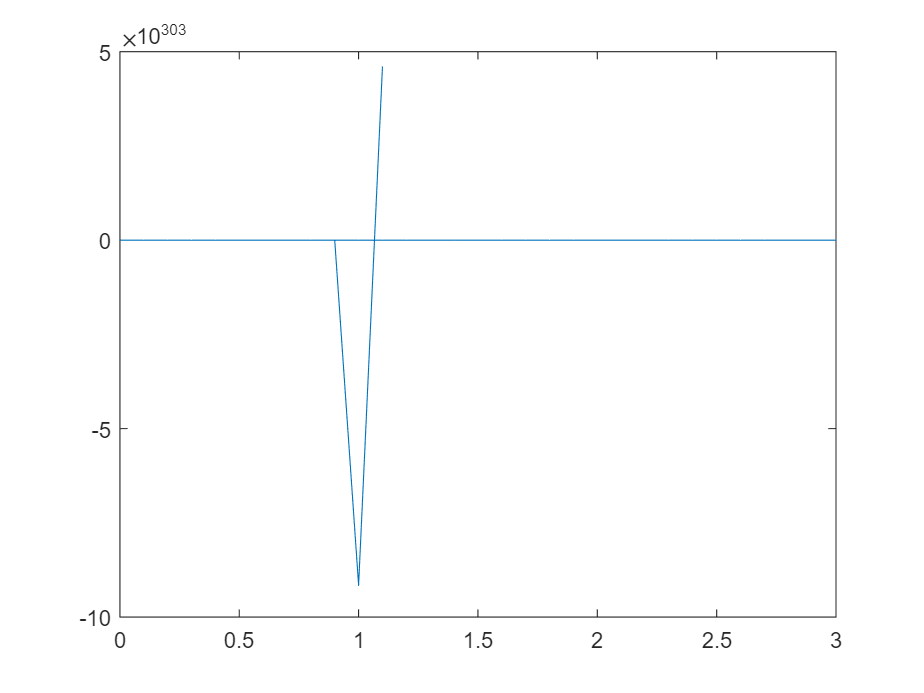






% Интегрируем систему 
[t_plot, x_cl_adapt]= ode45(@(t,x) ...
    quad_model_RHS(t, A, B, K, A_m, B_m, x, g, @MIMO_adaptive_control), tspan, ICs);
figure('Name', 'Extended system trajectories along adaptive control');
plot(t_plot, x_cl_adapt); %динамика всего вектора состояний

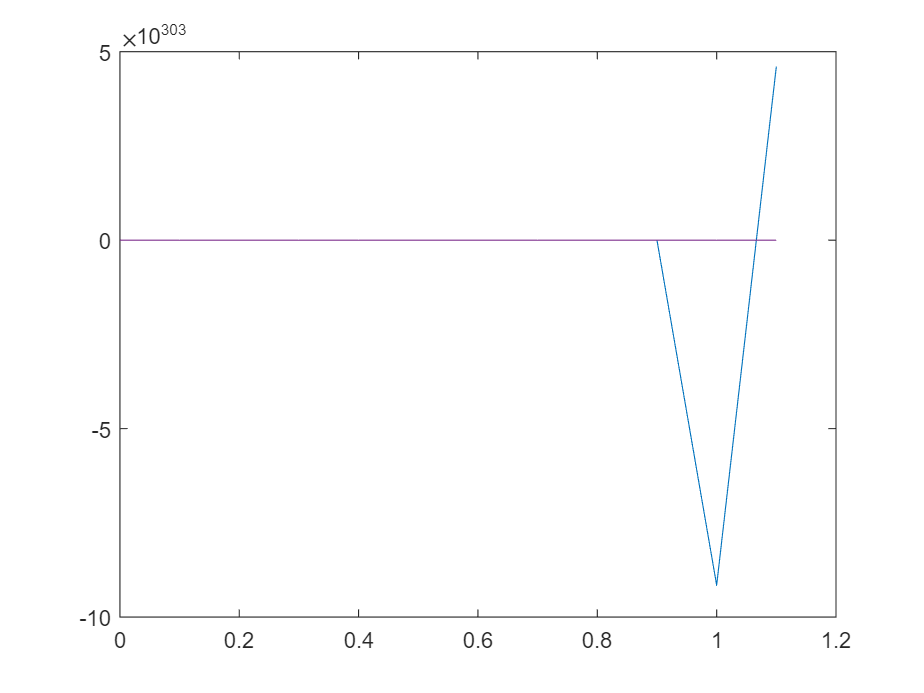


figure('Name', ['Tracking errors along adaptive control']);
plot(t_plot, x_cl_adapt(:, [1:4]) - x_cl_adapt(:, [5:8]) ); %динамика всего вектора состояний

Объявим все нужные нам функции

function dxdt = quad_model_RHS(t, A, B, K, A_m, B_m, x, g, u_ref)
dxdt = zeros(size(x,1), size(x,2));
cur_g = g(t);

% Размерности системы
n = 4; %состояние
r = 1; %управление
l = 1; %вектор неопр. параметров

% Индексы для элементов подсистем а расширенном векторе
sys_x_indexes = 1:n;
x_m_indexes = (n+1) : (2*n);
hat_Theta_indexes = (2*n+1):(2*n + l*r);

sys_x = x(sys_x_indexes);
x_m = x(x_m_indexes);


hat_Theta = reshape(x(hat_Theta_indexes), r, l)';

%Задаем действие W
%w(x) = Theta^T * Phi(x) = [ -k1; k2 ]^T * [x2; x4];
% k1 > 0; k2 > 0;

k1 = 0.1;
Theta = -k1;  
Phi = sys_x(3);
w = Theta * Phi;


if isequal(u_ref, @MIMO_adaptive_control)
    u = MIMO_adaptive_control(K, sys_x, r, hat_Theta, Phi, cur_g);
else
    u = LQR_control(K, sys_x);
end

%Первые части для расш вектора
%Правая яасть замкнутой системы
dxdt(sys_x_indexes) = A*sys_x + B*(u+w);
% Правая часть для замкнутой ЭМ
dxdt(x_m_indexes) = A_m*x_m + B_m*cur_g;

e = sys_x - x_m;
d_hat_Theta = get_d_hat_Theta(n, l, A_m, B, Phi, e);

%Правая часть для Theta
dxdt(hat_Theta_indexes)= reshape(d_hat_Theta', [], 1);
end

function u =LQR_control(K, sys_x)
u = K*sys_x;
end

function u = MIMO_adaptive_control(K, sys_x, r, hat_Theta, Phi, cur_g)
K_x = - K;
K_g = eye(r);
u = K_x * sys_x + K_g * cur_g - hat_Theta' * Phi;
end

function d_hat_Theta = get_d_hat_Theta(n, l, A_m, B, Phi, e)
G = eye(l);
Q = eye(n);
P = lyap(A_m, Q);

d_hat_Theta = G*Phi*e'*P*B;
end
